clearvars
close all
clc

2-D Gaussian


$$z = A\left\{1-e^{-\left(a(x-x_0)^2+b(x-x_0)(y-y_0)+c(y-y_0)^2\right)}\right\}$$


A = 1;
a = 1/2;
b = 1/4;
c = a;
x0 = .5;
y0 = 1;

% f = @(x,y) A*(1-exp(-(a*(x-x0).^2+b*(x-x0).*(y'-y0)+c*(y'-y0).^2)));
ax = gca;
N = 500;
x = -2 + (2+2)*rand(N,1);
y = -3 + (3+3)*rand(N,1);
z = A*(1-exp(-(a*(x-x0).^2+b*(x-x0).*(y-y0)+c*(y-y0).^2))).*(1+.1*rand(N,1));
hold(ax)

Current plot held


%surf(ax,x,y,z)
% formula(@f)
[X,Y] = meshgrid(x,y);
plot3(ax,x,y,z,'ro')
view(ax,3)
ax.DataAspectRatioMode = "manual";
ax.DataAspectRatio = [1 1 1] ;
ft = fittype( @(A,a,b,c,x0,y0,x,y)f(A,a,b,c,x0,y0,x,y), ...
            'independent', {'x', 'y'},'dependent', 'z' )

ft =      General model:
     ft(A,a,b,c,x0,y0,x,y) = f(A,a,b,c,x0,y0,x,y)

opts = fitoptions( ft );
opts.Lower = [0, 0, 0, 0, 0, 0];
opts.Robust = 'LAR';
opts.StartPoint = [0.5, 0.5, 0.5, 0.5, 0.5, 0.5];

[sf, gof] = fit( [x, y], z, ft, opts)

Fitting stopped because the number of iterations or function evaluations exceeded the specified maximum.

     General model:
     sf(x,y) = f(A,a,b,c,x0,y0,x,y)
     Coefficients (with 95% confidence bounds):
       A =       1.056  (1.052, 1.059)
       a =      0.5024  (0.4933, 0.5114)
       b =      0.2464  (0.234, 0.2587)
       c =       0.492  (0.4838, 0.5002)
       x0 =      0.4958  (0.4872, 0.5045)
       y0 =       1.002  (0.9938, 1.01)



gof = struct with fields:
           sse: 0.2782
       rsquare: 0.9932
           dfe: 494
    adjrsquare: 0.9932
          rmse: 0.0237


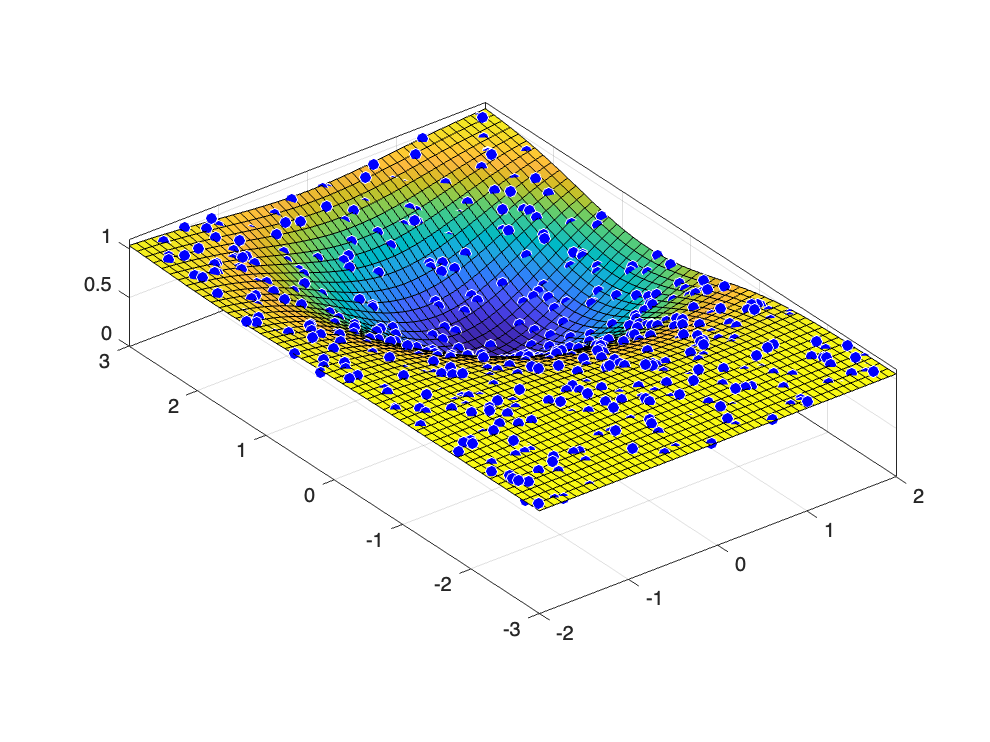

plot(sf,[x,y],z)

function z = f(A,a,b,c,x0,y0,x,y)
z = A*(1-exp(-(a*(x-x0).^2+b*(x-x0).*(y-y0)+c*(y-y0).^2)));
end